%% AAE 532 HW 5 Problem 1
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps5';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format longG;

% Load the GMAT data
warning('off','all');
reportDir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\gmat\ps5\reports';
for i = 0:3
    for j = 1:4
        if j == 1
            T(i+1).earthpointmass = readtable( ...
                fullfile(reportDir,"ps5_p1_"+num2str(i)+num2str(j)+".txt"));
        elseif j == 2
            T(i+1).earthmoon = readtable( ...
                fullfile(reportDir,"ps5_p1_"+num2str(i)+num2str(j)+".txt"));
        elseif j == 3
            T(i+1).earthsun = readtable( ...
                fullfile(reportDir,"ps5_p1_"+num2str(i)+num2str(j)+".txt"));
        else
            T(i+1).earthmoonsun = readtable( ...
                fullfile(reportDir,"ps5_p1_"+num2str(i)+num2str(j)+".txt"));
        end
    end
end

warning("on");

% Process the data to filter out the unnecessary values
for i = 1:4
    for j = 1:4
        if j == 1
           t =  T(i).earthpointmass.Sat1_Earth_RMAG;
           x1 = T(i).earthpointmass.Sat1_Earth_RMAG(1);
           x2 = T(i).earthpointmass.Sat1_Earth_RMAG(end);
           XX = find(t ~= x1 & t ~= x2);
        elseif j == 2
           t =  T(i).earthmoon.Sat2_Earth_RMAG;
           y1 = T(i).earthmoon.Sat2_Earth_RMAG(1);
           y2 = T(i).earthmoon.Sat2_Earth_RMAG(end);
           YY = find(t ~= y1 & t ~= y2);
        elseif j == 3
           t =  T(i).earthsun.Sat3_Earth_RMAG;
           z1 = T(i).earthsun.Sat3_Earth_RMAG(1);
           z2 = T(i).earthsun.Sat3_Earth_RMAG(end);
           ZZ = find(t ~= z1 & t ~= z2);
       else
           t =  T(i).earthmoonsun.Sat4_Earth_RMAG;
           w1 = T(i).earthmoonsun.Sat4_Earth_RMAG(1);
           w2 = T(i).earthmoonsun.Sat4_Earth_RMAG(end);
           WW = find(t ~= w1 & t ~= w2);
        end
    end
    T(i).earthpointmass = T(i).earthpointmass([XX(1)-1, XX', XX(end)+1], :);
    T(i).earthmoon      =      T(i).earthmoon([YY(1)-1, YY', YY(end)+1], :);
    T(i).earthsun       =       T(i).earthsun([ZZ(1)-1, ZZ', ZZ(end)+1], :);
    T(i).earthmoonsun   =   T(i).earthmoonsun([WW(1)-1, WW', WW(end)+1], :);

    % Compute the FPA
    d1 = T(i).earthpointmass.Sat1_Earth_HMAG;
    d2 = T(i).earthpointmass.Sat1_Earth_RMAG;
    d3 = T(i).earthpointmass.Sat1_EarthMJ2000Eq_VMAG;
    T(i).earthpointmass.Sat1_EarthMJ2000Eq_FPA = acosd(d1 ./ d2 ./ d3);
    dd = find(T(i).earthpointmass.Sat1_Earth_TA > 180);
    T(i).earthpointmass.Sat1_EarthMJ2000Eq_FPA(dd) = -T(i).earthpointmass.Sat1_EarthMJ2000Eq_FPA(dd);
    
    d1 = T(i).earthmoon.Sat2_Earth_HMAG;
    d2 = T(i).earthmoon.Sat2_Earth_RMAG;
    d3 = T(i).earthmoon.Sat2_EarthMJ2000Eq_VMAG;
    T(i).earthmoon.Sat2_EarthMJ2000Eq_FPA = acosd(d1 ./ d2 ./ d3);
    dd = find(T(i).earthmoon.Sat2_Earth_TA > 180);
    T(i).earthmoon.Sat2_EarthMJ2000Eq_FPA(dd) = -T(i).earthmoon.Sat2_EarthMJ2000Eq_FPA(dd);
    
    d1 = T(i).earthsun.Sat3_Earth_HMAG;
    d2 = T(i).earthsun.Sat3_Earth_RMAG;
    d3 = T(i).earthsun.Sat3_EarthMJ2000Eq_VMAG;
    T(i).earthsun.Sat3_EarthMJ2000Eq_FPA = acosd(d1 ./ d2 ./ d3);
    dd = find(T(i).earthsun.Sat3_Earth_TA > 180);
    T(i).earthsun.Sat3_EarthMJ2000Eq_FPA(dd) = -T(i).earthsun.Sat3_EarthMJ2000Eq_FPA(dd);
    
    d1 = T(i).earthmoonsun.Sat4_Earth_HMAG;
    d2 = T(i).earthmoonsun.Sat4_Earth_RMAG;
    d3 = T(i).earthmoonsun.Sat4_EarthMJ2000Eq_VMAG;
    T(i).earthmoonsun.Sat4_EarthMJ2000Eq_FPA = acosd(d1 ./ d2 ./ d3);
    dd = find(T(i).earthmoonsun.Sat4_Earth_TA > 180);
    T(i).earthmoonsun.Sat4_EarthMJ2000Eq_FPA(dd) = -T(i).earthmoonsun.Sat4_EarthMJ2000Eq_FPA(dd);
end

% a = []; e = []; rp = []; E = []; h = [];
% for i = 1:4
%     t1 = T(i).earthpointmass;
%     t2 = T(i).earthmoon;
%     t3 = T(i).earthsun;
%     t4 = T(i).earthmoonsun;
%     for j = 1:4
%         if j == 1
%             a(i,j)  = mean(t1.Sat1_Earth_SMA);
%             e(i,j)  = mean(t1.Sat1_Earth_ECC);
%             rp(i,j) = mean(t1.Sat1_Earth_RadPer);
%             En(i,j) = mean(t1.Sat1_Earth_Energy);
%             h(i,j)  = mean(t1.Sat1_Earth_HMAG);
%         elseif j == 2
%             a(i,j)  = mean(t2.Sat2_Earth_SMA);
%             e(i,j)  = mean(t2.Sat2_Earth_ECC);
%             rp(i,j) = mean(t2.Sat2_Earth_RadPer);
%             En(i,j) = mean(t2.Sat2_Earth_Energy);
%             h(i,j)  = mean(t2.Sat2_Earth_HMAG);
%         elseif j == 3
%             a(i,j)  = mean(t3.Sat3_Earth_SMA);
%             e(i,j)  = mean(t3.Sat3_Earth_ECC);
%             rp(i,j) = mean(t3.Sat3_Earth_RadPer);
%             En(i,j) = mean(t3.Sat3_Earth_Energy);
%             h(i,j)  = mean(t3.Sat3_Earth_HMAG);
%         else
%             a(i,j)  = mean(t4.Sat4_Earth_SMA);
%             e(i,j)  = mean(t4.Sat4_Earth_ECC);
%             rp(i,j) = mean(t4.Sat4_Earth_RadPer);
%             En(i,j) = mean(t4.Sat4_Earth_Energy);
%             h(i,j)  = mean(t4.Sat4_Earth_HMAG);
%         end
%     end
% end

% Get the last values for each column
a = []; e = []; rp = []; E = []; h = []; rf = []; vf = []; TA_f = []; FPA_f = [];
for i = 1:4
    t1 = T(i).earthpointmass;
    t2 = T(i).earthmoon;
    t3 = T(i).earthsun;
    t4 = T(i).earthmoonsun;
    for j = 1:4
        if j == 1
            a(i,j)     = t1.Sat1_Earth_SMA(end);
            e(i,j)     = t1.Sat1_Earth_ECC(end);
            rp(i,j)    = t1.Sat1_Earth_RadPer(end);
            En(i,j)    = t1.Sat1_Earth_Energy(end);
            h(i,j)     = t1.Sat1_Earth_HMAG(end);
            rf(i,j)    = t1.Sat1_Earth_RMAG(end);
            vf(i,j)    = t1.Sat1_EarthMJ2000Eq_VMAG(end);
            TA_f(i,j)  = t1.Sat1_Earth_TA(end);
            FPA_f(i,j) = t1.Sat1_EarthMJ2000Eq_FPA(end);
        elseif j == 2
            a(i,j)     = t2.Sat2_Earth_SMA(end);
            e(i,j)     = t2.Sat2_Earth_ECC(end);
            rp(i,j)    = t2.Sat2_Earth_RadPer(end);
            En(i,j)    = t2.Sat2_Earth_Energy(end);
            h(i,j)     = t2.Sat2_Earth_HMAG(end);
            rf(i,j)    = t2.Sat2_Earth_RMAG(end);
            vf(i,j)    = t2.Sat2_EarthMJ2000Eq_VMAG(end);
            TA_f(i,j)  = t2.Sat2_Earth_TA(end);
            FPA_f(i,j) = t2.Sat2_EarthMJ2000Eq_FPA(end);
        elseif j == 3
            a(i,j)     = t3.Sat3_Earth_SMA(end);
            e(i,j)     = t3.Sat3_Earth_ECC(end);
            rp(i,j)    = t3.Sat3_Earth_RadPer(end);
            En(i,j)    = t3.Sat3_Earth_Energy(end);
            h(i,j)     = t3.Sat3_Earth_HMAG(end);
            rf(i,j)    = t3.Sat3_Earth_RMAG(end);
            vf(i,j)    = t3.Sat3_EarthMJ2000Eq_VMAG(end);
            TA_f(i,j)  = t3.Sat3_Earth_TA(end);
            FPA_f(i,j) = t3.Sat3_EarthMJ2000Eq_FPA(end);
        else
            a(i,j)     = t4.Sat4_Earth_SMA(end);
            e(i,j)     = t4.Sat4_Earth_ECC(end);
            rp(i,j)    = t4.Sat4_Earth_RadPer(end);
            En(i,j)    = t4.Sat4_Earth_Energy(end);
            h(i,j)     = t4.Sat4_Earth_HMAG(end);
            rf(i,j)    = t4.Sat4_Earth_RMAG(end);
            vf(i,j)    = t4.Sat4_EarthMJ2000Eq_VMAG(end);
            TA_f(i,j)  = t4.Sat4_Earth_TA(end);
            FPA_f(i,j) = t4.Sat4_EarthMJ2000Eq_FPA(end);
        end
    end
end

% Get array for data
arr1 = [a(1,:);e(1,:);rp(1,:);En(1,:);h(1,:);rf(1,:);vf(1,:);TA_f(1,:);FPA_f(1,:)];
arr2 = [a(2,:);e(2,:);rp(2,:);En(2,:);h(2,:);rf(2,:);vf(2,:);TA_f(2,:);FPA_f(2,:)];
arr3 = [a(3,:);e(3,:);rp(3,:);En(3,:);h(3,:);rf(3,:);vf(3,:);TA_f(3,:);FPA_f(3,:)];
arr4 = [a(4,:);e(4,:);rp(4,:);En(4,:);h(4,:);rf(4,:);vf(4,:);TA_f(4,:);FPA_f(4,:)];

% Convert arrays to table 
M1 = array2table(arr1);
M2 = array2table(arr2);
M3 = array2table(arr3);
M4 = array2table(arr4);

% Save table data as excel file 
warning('off','MATLAB:xlswrite:AddSheet'); %optional
writetable(M1,fullfile(fdir, 'p1_data.xlsx'),'Sheet',1);
writetable(M2,fullfile(fdir, 'p1_data.xlsx'),'Sheet',2);
writetable(M3,fullfile(fdir, 'p1_data.xlsx'),'Sheet',3);
writetable(M4,fullfile(fdir, 'p1_data.xlsx'),'Sheet',4);

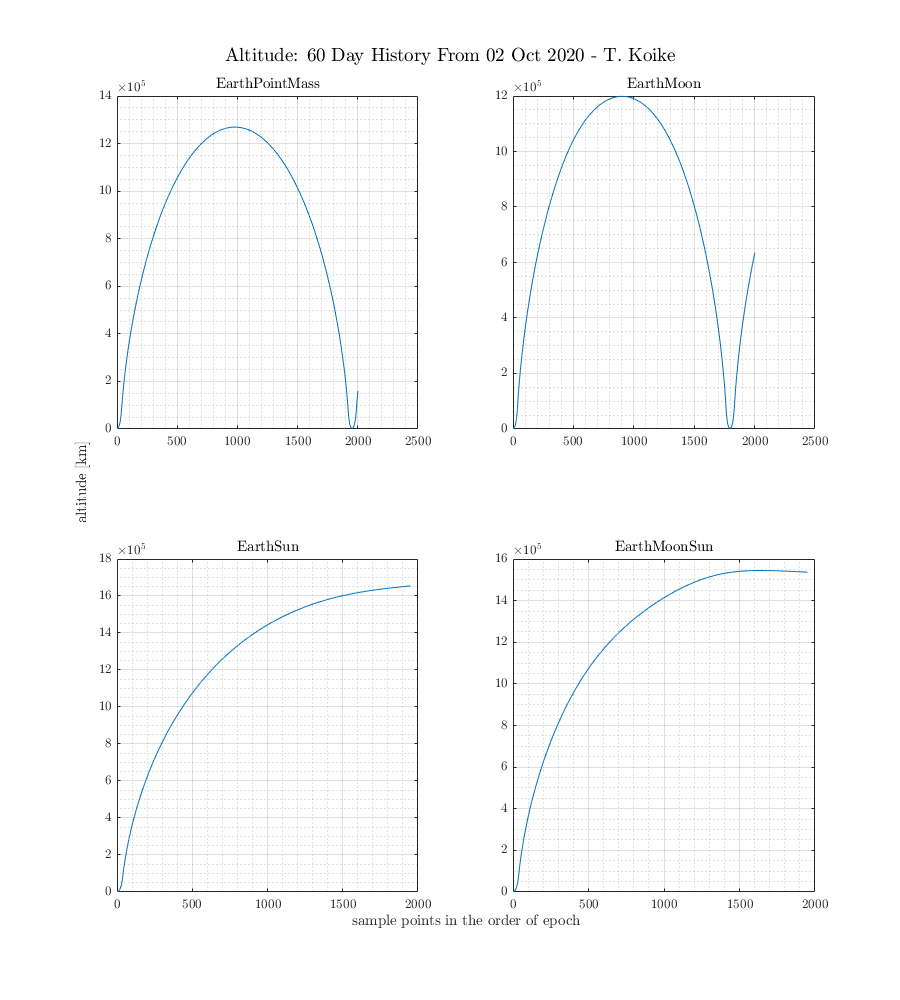

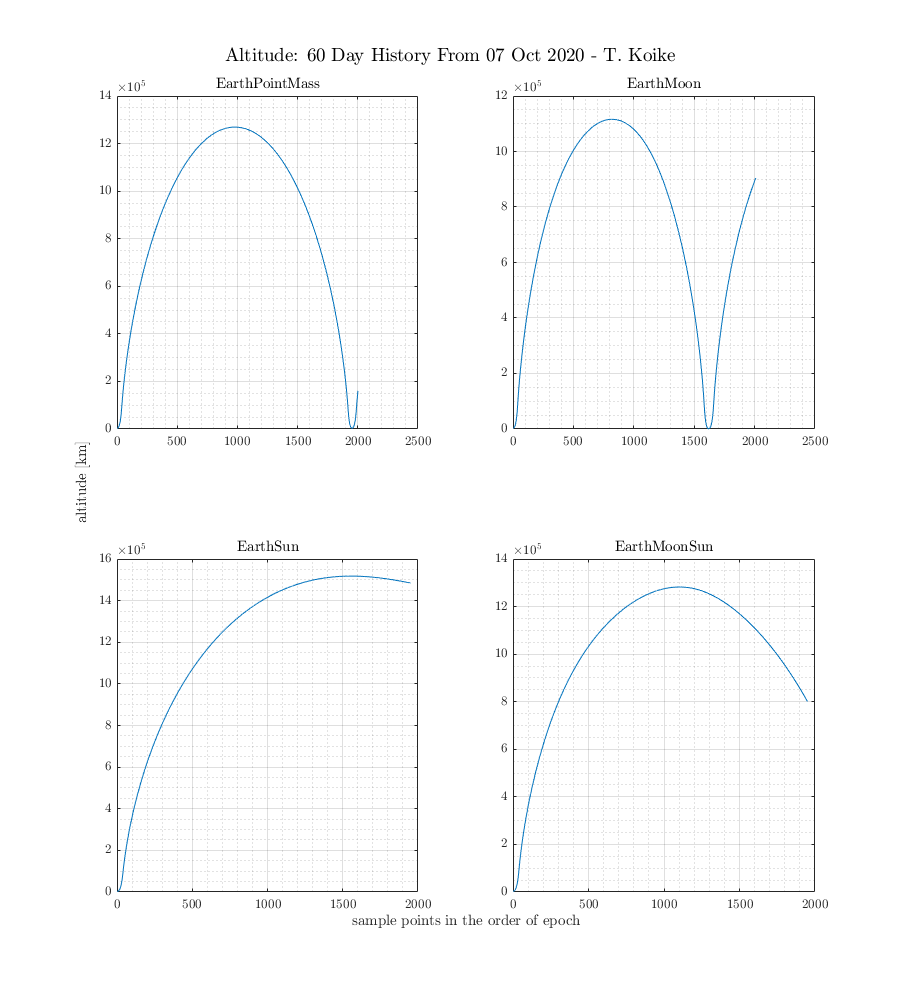

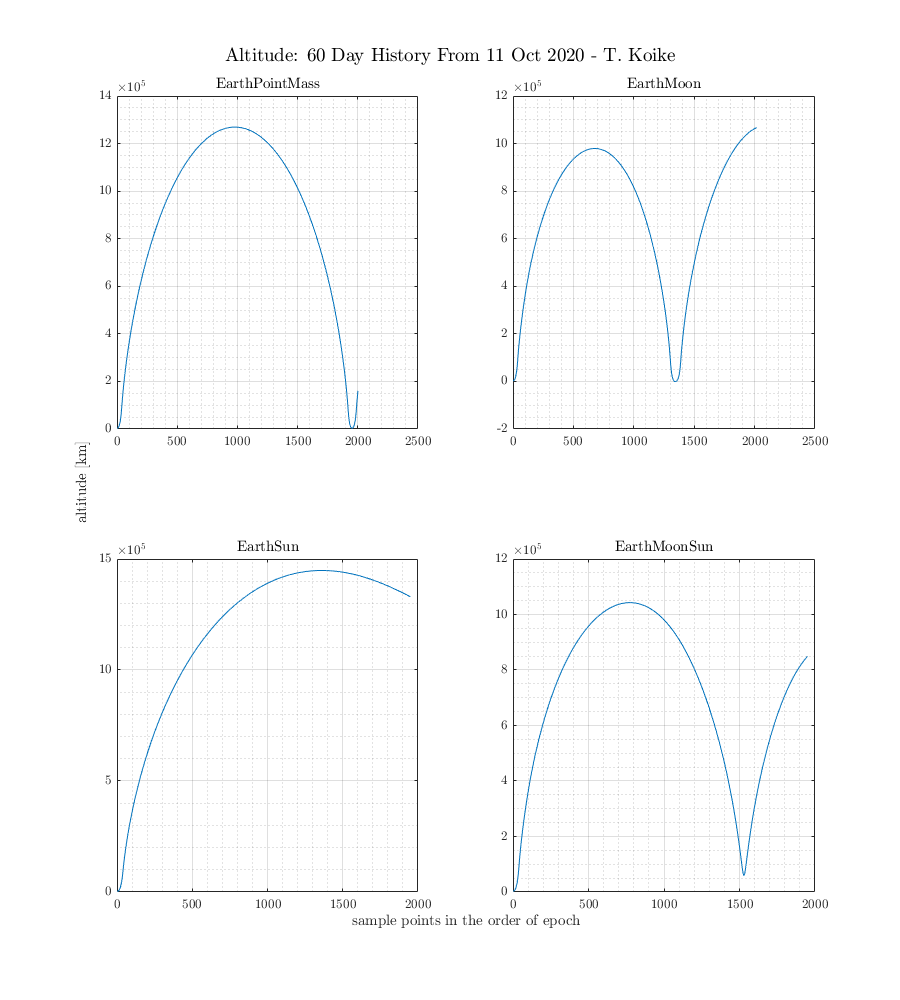

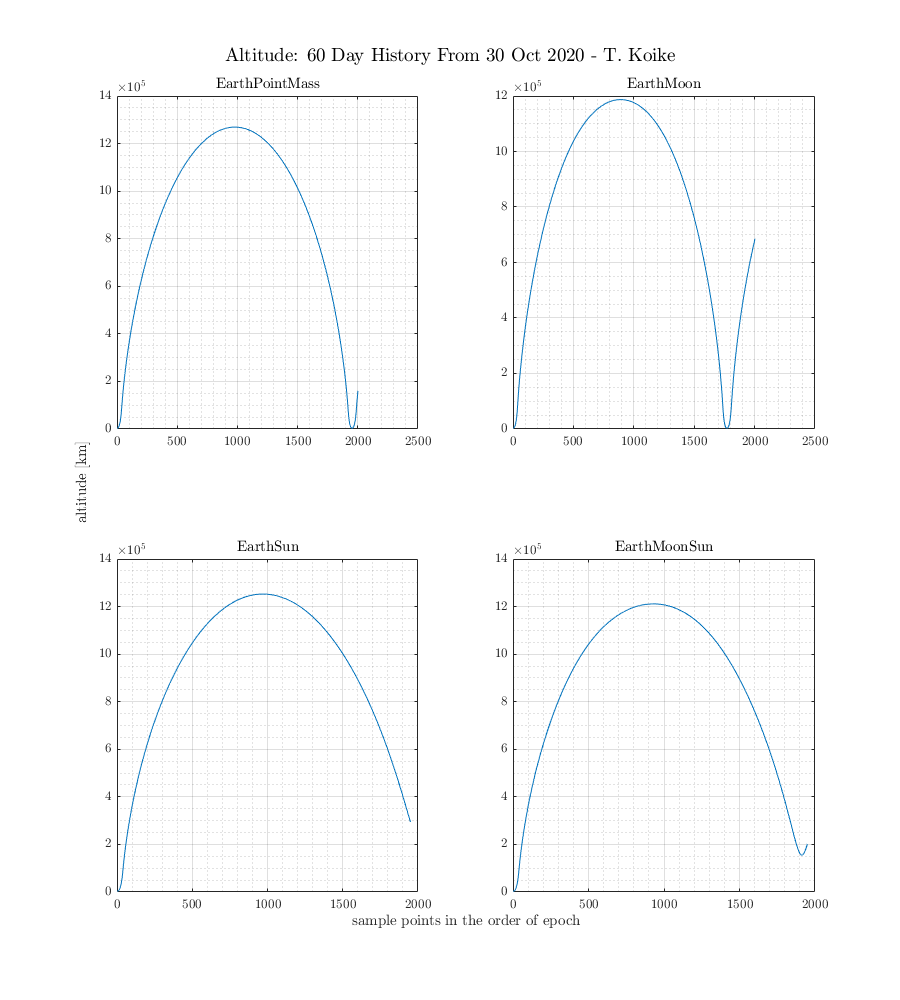

% Plotting 

for i = 1:4
    t1 = T(i).earthpointmass;
    t2 = T(i).earthmoon;
    t3 = T(i).earthsun;
    t4 = T(i).earthmoonsun;
    
    fig = figure("Renderer","painters", "Position",[10 10 900 1000]);
    subplot(2,2,1)
    plot(t1.Sat1_Earth_Altitude)
    title('EarthPointMass')
    grid on; grid minor; box on;
    subplot(2,2,2)
    plot(t2.Sat2_Earth_Altitude)
    title('EarthMoon')
    grid on; grid minor; box on;
    subplot(2,2,3)
    plot(t3.Sat3_Earth_Altitude)
    title('EarthSun')
    grid on; grid minor; box on;
    subplot(2,2,4)
    plot(t4.Sat4_Earth_Altitude)
    title('EarthMoonSun')
    grid on; grid minor; box on;
    % Give common xlabel and ylabel to your figure
    han=axes(fig,'visible','off'); 
    han.XLabel.Visible='on';
    han.YLabel.Visible='on';
    xlabel(han,'sample points in the order of epoch');
    ylabel(han,'altitude [km]');
    
    ch_str = ["02 Oct 2020", "07 Oct 2020", "11 Oct 2020", "30 Oct 2020"];
    title_str = 'Altitude: 60 Day History From ' + ch_str(i) + ' - T. Koike';
    sgtitle(title_str)
    
    file_str = 'alt' + ch_str(i) + '.png';
    saveas(fig, fullfile(fdir, file_str));
end